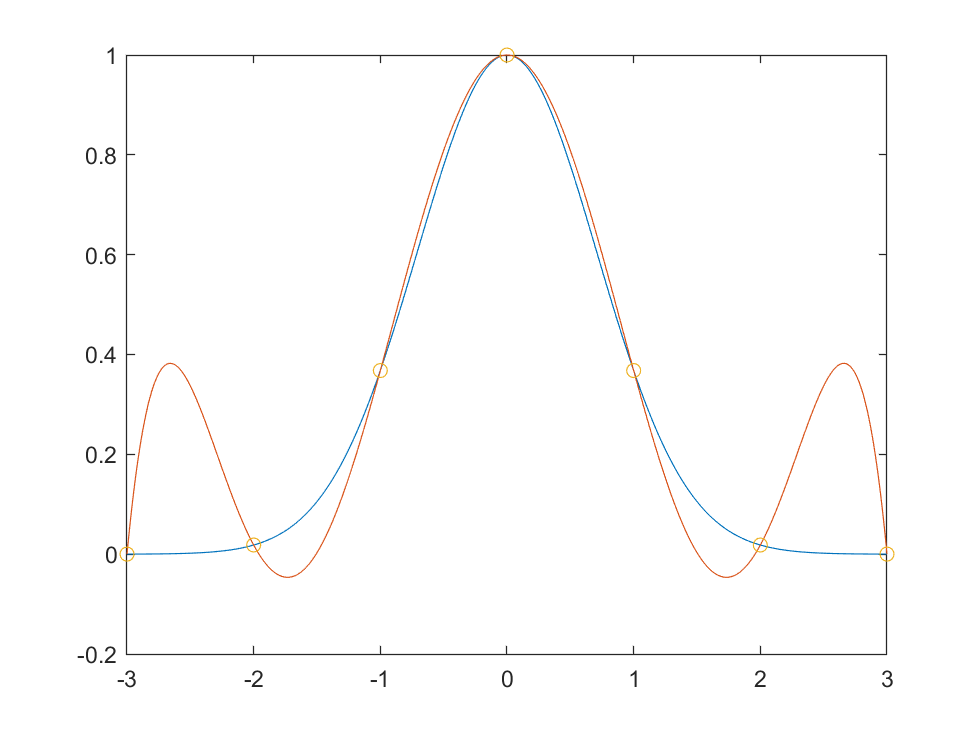

% (a)
% function f1
f1 =@(x) (exp(-x.^2));

% data points of f1
datx = -3:1:3;
daty = f1(datx);

% points to interpolate f1
x = -3:0.01:3;

% Polynomial interpolant of f1
P5 = Newtons_divided_differences(x,datx,daty);

% plot of the function
plot(x,f1(x));
hold on;

% plot of the interpolants
plot(x',P5);

% plot of the data set
scatter(datx,f1(datx));
hold off;


% (b)
% Compared to my result from Lagrange_poly, my result from Newtons_divided_differences 
% is the same.

function [y] = Newtons_divided_differences(x,datx,daty)
    sx = size(x,2);
    sdatx = size(datx,2);
    F = ones(1,sdatx);
    y = ones(1,sx);
    for i = 1:sdatx
        F(i) = daty(i);
    end
    for i = 2:sdatx
        F(i:sdatx) = (F(i:sdatx)-F(i-1:sdatx-1))./(datx(i:sdatx)-datx(1:sdatx-i+1));
    end
    y = y * F(sdatx);
    for i = 1:sdatx-1
        y = F(sdatx-i) + (x-datx(sdatx-i)).*y;
    end
    y = y';
end